# **Lab 5 Simulation Results**

heartbeat_data = csvread('blood_simulation_plot.csv',3);
heartbeat_simulation_1 = heartbeat_data((1:end),1);
heartbeat_simulation_2 = heartbeat_data((1:end),2);
heartbeat_simulation_3 = heartbeat_data((1:end),3);
heartbeat_simulation_4 = heartbeat_data((1:end),4);

sixteens = ones(1498,1) * 16

sixteens =     16
    16
    16
    16
    16
    16
    16
    16
    16
    16


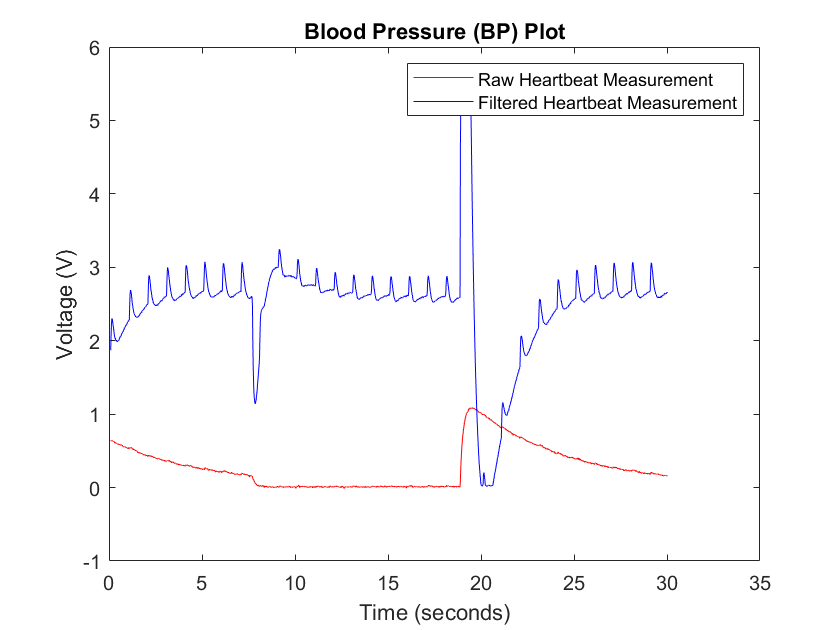

clf;
plot(heartbeat_simulation_1+sixteens, heartbeat_simulation_2,'r')
hold on
plot(heartbeat_simulation_3+sixteens, heartbeat_simulation_4,'b')

title("Blood Pressure (BP) Plot")
xlabel("Time (seconds)")
ylabel("Voltage (V)")
legend("Raw Heartbeat Measurement","Filtered Heartbeat Measurement")

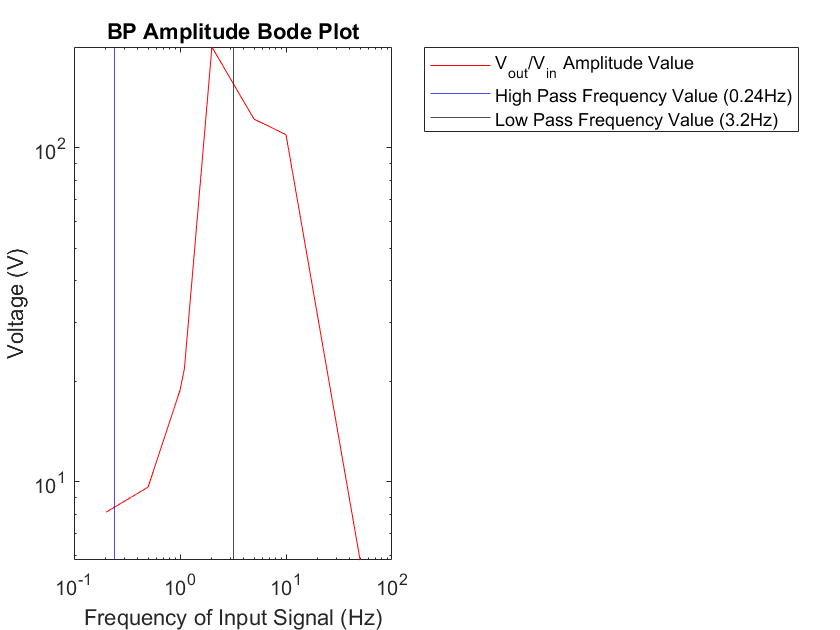

Hz = [0.2;0.5;1.0;1.1;2.0;5.0;10.0;50.0;100.0];
V_in = [0.0842; 0.0863; 0.0894; 0.0812; 0.00913; 0.00906; 0.00901; 0.0909; 0.0914];
V_out = [0.6822; 0.8320; 1.680; 1.769; 1.830; 1.104; 0.987; 0.530; 0.124];
samp_rate = [10;20;50;100;200;500;1000;5000;10000];

clf;
figure
loglog(Hz(1:end-1),V_out(1:end-1)./V_in(1:end-1),'r')
hold on
%plot(Hz(1:end-1), V_out(1:end-1),'b')
title("BP Amplitude Bode Plot")
xlabel("Frequency of Input Signal (Hz)")
ylabel("Voltage (V)")
hold on
xline(0.24,'b')
hold on
xline(3.2,'k')

legend("V_{out}/V_{in} Amplitude Value","High Pass Frequency Value (0.24Hz)", "Low Pass Frequency Value (3.2Hz)", "Location","bestoutside")